warning off
init_unfold


Starting unfold toolbox.
Adding subfolders and other toolboxes to path...
Done.


warning on

# Introduction

Subjects are exploring a face stimulus. Using an eyetracker and the EEG-Eye toolbox we add markers of saccade onsets into our EEG-Data. The data were cleaned for eye-movement related artefacts using ICA.

In this tutorial we try to disentangle stimulus related ERPs and (micro)saccade related ERPs.

EEG  = pop_loadset('C:\Users\behinger\Dropbox\deconv_olaf\workshop\data\facestudy_integrated.set')

pop_loadset(): loading file C:\Users\behinger\Dropbox\deconv_olaf\workshop\data\facestudy_integrated.set ...


EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

# Defining the design

cfgDesign = [];
cfgDesign.eventtypes = {{'saccade'},{'S121','S122','S123'}}; % we model the saccadeonset and the stimulus
cfgDesign.formula = {'y ~ 1 + spl(sac_amplitude,10)','y~1'}; % 10 splines are generated; One needs to be careful to not overfit the data, regularization or cross validation can help here.
EEG = uf_designmat(EEG,cfgDesign);

Multiple events with separate model-formula detected
Modeling 3241 event(s) of [saccade] using formula: y~1 
The spline that got removed due to collinearity in the basis set (as intended) for the effect sac_amplitude has its peak at 1.270010
This does not mean that the event-intercept represents this value! 
Modeling 3241 event(s) of [S121,S122,S123] using formula: y~1 


The term `spl(sac_amplitude,10)` creates 10 splines over our predictor.  

We can visualise the set of splines  using:

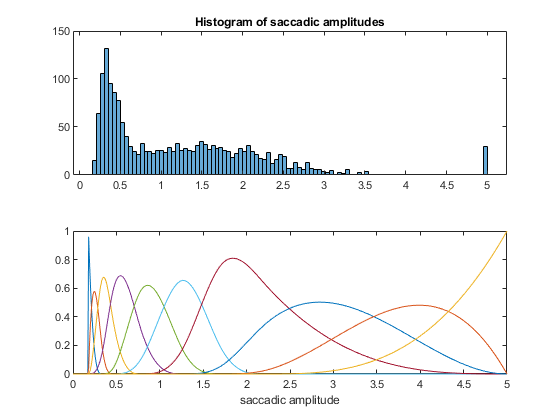

spl = EEG.unfold.splines{1};

subplot(2,1,1),histogram(spl.paramValues,100),title('Histogram of saccadic amplitudes')

splineSet = spl.splinefunction(linspace(0,5,500),spl.knots);
subplot(2,1,2),plot(linspace(0,5,500),splineSet),xlabel('saccadic amplitude')

The default setting is to put the splines at points of the quantiles of the variable. This ensures that in regions with a lot of data, lots of splines are generated and in regions with sparse data,  broad splines are used. One could also put the splines in a linear or logarithmical way or define the knotsequence manually.

To understand better what basis function do, it might be helpful to have a look at the sorted designmatrix:

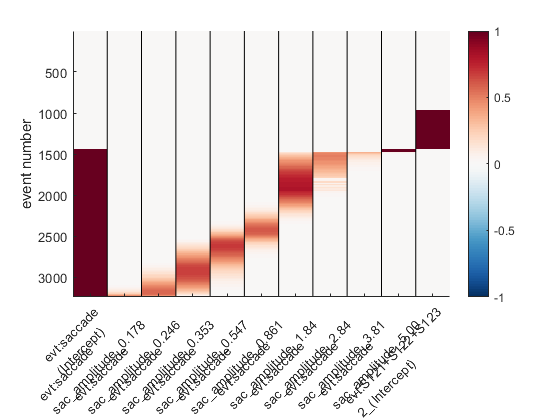

uf_plotDesignmat(EEG,'sort',1)

The sorted designmatrix shows overlapping predictors, these are the splines for saccade amplitude. There is one predictor removed (between sac_amp 1.5 & 2.9). This is because we have an intercept in the model and else the model would be overcomplete. Not that the empty events (all grey rows) are events that are not modeled.

cfgTimeexpand = [];
cfgTimeexpand.timelimits = [-.3,.6];

EEG = uf_timeexpandDesignmat(EEG,cfgTimeexpand);


uf_timeexpandDesignmat(): Timeexpanding the designmatrix...
...done


EEG = uf_continuousArtifactExclude(EEG,struct('winrej',winrej)); % we find data using a simple threshold tool. More complex algorithms or manual cleaning is recommended!

Portions of data removed split up by each event in EEG.event
Type: S 99           Modelled Eventtime:    431.10s 	 rejected eventtime:      0.00s 	 percent removed:  0.0%
Type: S100           Modelled Eventtime:      0.90s 	 rejected eventtime:      0.00s 	 percent removed:  0.0%
Type: S121           Modelled Eventtime:    143.10s 	 rejected eventtime:      0.00s 	 percent removed:  0.0%
Type: S122           Modelled Eventtime:    144.00s 	 rejected eventtime:      0.00s 	 percent removed:  0.0%
Type: S123           Modelled Eventtime:    144.00s 	 rejected eventtime:      0.00s 	 percent removed:  0.0%
Type: S200           Modelled Eventtime:      0.90s 	 rejected eventtime:      0.00s 	 percent removed:  0.0%
Type: S255           Modelled Eventtime:    430.20s 	 rejected eventtime:      0.00s 	 percent removed:  0.0%
Type: saccade        Modelled Eventtime:    647.29s 	 rejected eventtime:      0.00s 	 percent removed:  0.0%

removing 0.00% of rows from design matrix (fill it with ze

EEG= uf_glmfit(EEG);


uf_glmfit(): Fitting deconvolution model...solving the equation system

solving electrode 1 (of 1 electrodes in total)... 75 iterations, took 0.8s
 LMfit finished 


# Plot the results

Currently the spline-predictor is still separated in intercept + 9 spline-betas. The relationship for e.g. the P100 can be visualized. We start with a simple investigation of the raw betas, without undoing the spline-basisset

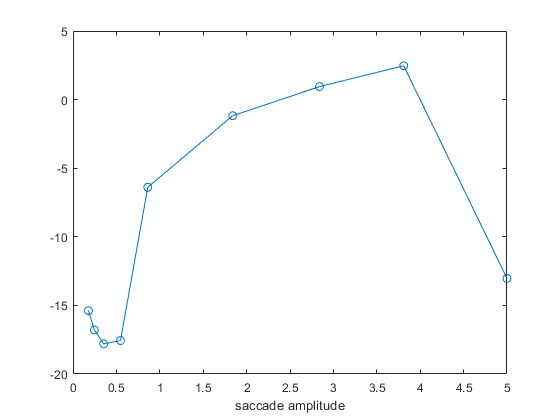

ufresult= uf_condense(EEG);

sac_amp_ix = cellfun(@(x)~isempty(x),(strfind({ufresult.param.name},'sac_amplitude'))); % get all betas related to sac_amplitude
timeix = get_min(0.115,ufresult.times); % somewhere around the p100

splinevalue = [ufresult.param(sac_amp_ix).value];

figure;
plot(splinevalue,squeeze(ufresult.beta(1,timeix,sac_amp_ix)),'-o'),xlabel('saccade amplitude')

This plot is still lacking the intercept (a DC-offset) and of course, these betas represent only weights to the above plotted set of basisfunctions.

 In order to get a better picture, let's multiply the betas with the basis function to get an estimate in the predictor-value-domain.

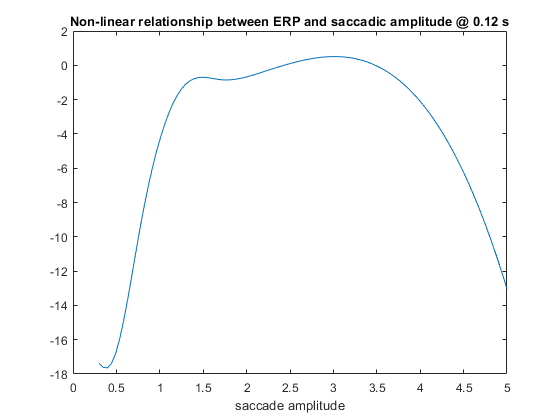


ufresult= uf_predictContinuous(ufresult,'predictAt',{{'sac_amplitude',linspace(0.3,5,100)}});
sac_amp_ix = cellfun(@(x)~isempty(x),(strfind({ufresult.param.name},'sac_amplitude'))); % get all betas related to sac_amplitude
y = ufresult.beta(1,timeix,sac_amp_ix); 
% we could add the intercept; it is a constant offset
%y = y + ufresult.beta(1,timeix,1);
plot([ufresult.param(sac_amp_ix).value],squeeze(y)),xlabel('saccade amplitude'),title(sprintf('Non-linear relationship between ERP and saccadic amplitude @ %.2f s',ufresult.times(timeix)))

It is clear from this plot, that there is a strongly non-linear relationship between saccade amplitude and ERP at around 100ms. 

**It's important to remember here, that above 3° saccade amplitude only very few saccades remain**. It is therefore important to not overinterpret this downward trend!

To really drive home the point we add the weighted splines to the plot:

ufresult= uf_condense(EEG);
sacX =linspace(0.3,5,500); % at which points to evaluate?

splineSet = spl.splinefunction(sacX,spl.knots);

beta = squeeze(ufresult.beta(1,timeix,1:end-1)); % end-1 because of the stimulus event predictor
splineEvaluated = bsxfun(@times,splineSet,beta'); % weight the basis functions by the betas, but don't add them

plot(sacX,splineEvaluated); hold all;

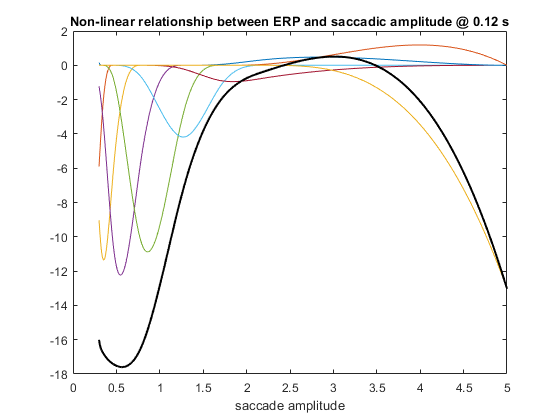

plot(sacX,sum(splineEvaluated,2),'k','LineWidth',1.5), % add the basis functions at each saccade-amplitude to get the modelfit
xlabel('saccade amplitude'),title(sprintf('Non-linear relationship between ERP and saccadic amplitude @ %.2f s',ufresult.times(timeix)))

As one can also see, the modelfit is a bit rough at the edges. this is to be expected because there is not much data for very small and very large splines.


plotting all parameters

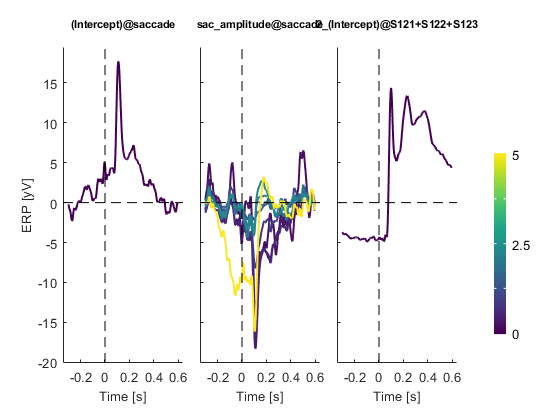

% The default parameters plot the predictor at its quantiles
ufpredict = uf_predictContinuous(ufresult); % evaluate the splines at the quantiles
uf_plotParam(ufpredict,'channel',1,'add_average',1);

Important notes to this plot:

- The lines represent saccade-amplitudes at the quantiles of the saccade amplitude distribution.

- There are outliers/bad estimates at the extremes. The yellow-curve has a very high noise level. This is because the last spline is only informed by a small amount of trials, it is usually highly unstable.

In order to get a more representative picture, we can utilize the `'predictAt' `option in the plot and put a linear spacing excluding the extremata

ufpredict= uf_predictContinuous(ufresult,'predictAt',{{'sac_amplitude',linspace(0.5,3,10)}});
ufmarginal = uf_addmarginal(ufpredict);

uf_addmarginal: working on field beta 
re-running uf_condense to recover unconverted splines 



plotting selected parameters

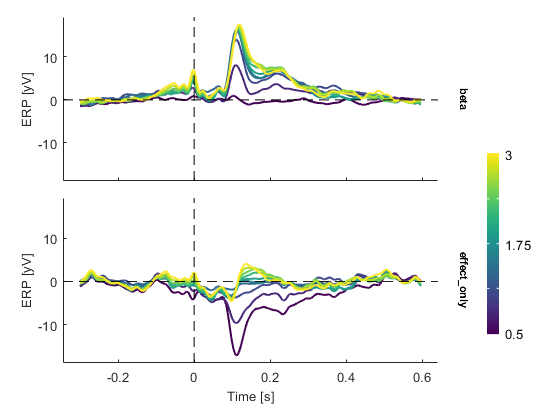

ufmarginal.effect_only = ufpredict.beta; % we are adding the predictor without the added intercept to show the difference
uf_plotParam(ufmarginal,'channel',1,'plotParam','sac_amplitude');

In the top row, the output of uf_addmarginal shows what happens after we add the mean value of all other predictors (in this case only the intercept). The lower plot can be seen as 'difference' waves